subject = "data/S001/S001"

subject = "data/S001/S001"

rec = 4

rec = 4

% subject = string(subj);
record = [];
for i=0:2
    record = [record string(num2str(rec+i*4, '%02d'))]
end

record = "04"

record = 1×2 string array
    "04"    "08"


data/S001/S001R04.edf


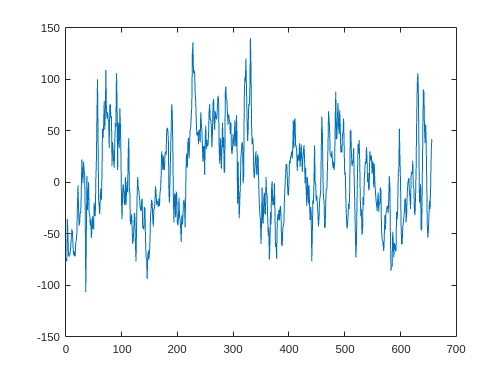

data/S001/S001R08.edf


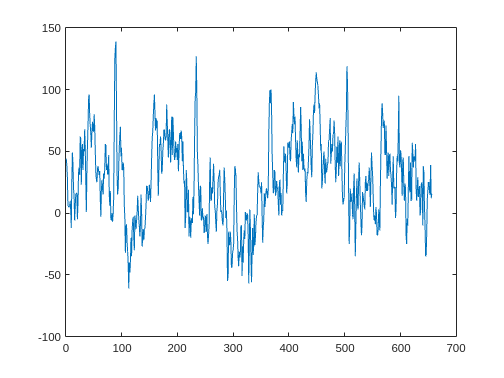

% disp(record);
t1s={};
t2s={};
for i=1:size(record, 2)
    recName = strcat(subject, "R", record(i), ".edf");
    recName = convertStringsToChars(recName);
    disp(recName);
    [eeg, fs, ts] = rdsamp(recName, 1:64);

    [T0, T1, T2] = getIntervals(recName, 'event', fs, length(ts));
    
    eeg = eeg.';

    for j=1:size(T1, 1)
        t1s{end+1} = eeg(:, T1(j,1):T1(j,2));
    end

    for j=1:size(T2,1)
        t2s{end+1} = eeg(:, T2(j,1):T2(j,2));
    end

    figure
    plot(t1s{end}(1, :).')
end


size(t1s)

ans =      1    16


size(t2s)

ans =      1    14


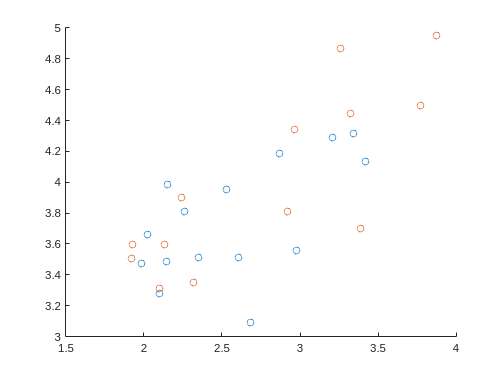



lvt1 = [];
lvt2 = [];
f = [0 8 8 13 13 fs/2]/(fs/2);
a = [0 0 1 1 0 0];
n = 75;
b = firls(n, f, a);

[W] = f_CSP(cell2mat(t1s(1)), cell2mat(t2s(1)));
t1s(1) = [];
t2s(1) = [];
for i=1:size(t1s, 2)
    cst = W * cell2mat(t1s(i));
    cse = [cst(1, :).', cst(size(cst,1), :).'].';
    csf = filter(b, 1, cse);
    lvt1(i, 1) = log(var(csf(1,:)));
    lvt1(i, 2) = log(var(csf(2,:)));
end
for i=1:size(t2s, 2)
    cst = W * cell2mat(t2s(i));
    cse = [cst(1, :).', cst(size(cst,1), :).'].';
    csf = filter(b, 1, cse);
    lvt2(i, 1) = log(var(csf(1,:)));
    lvt2(i, 2) = log(var(csf(2,:)));
end

figure
scatter(lvt1(:, 1), lvt1(:, 2));
hold on
scatter(lvt2(:, 1), lvt2(:, 2));


featF = 'featureVectors.txt';
clasF = 'referenceClass.txt';

fvf = fopen(featF, "wt");
rcf = fopen(clasF, "wt");

for i=1:size(lvt1, 1)
    fprintf(fvf, "%.8f %.8f\n", lvt1(i, 1), lvt1(i, 2));
    fprintf(rcf, "T1\n");
end
for i=1:size(lvt2, 1)
    fprintf(fvf, "%.8f %.8f\n", lvt2(i, 1), lvt2(i, 2));
    fprintf(rcf, "T2\n");
end
fclose(fvf);
fclose(rcf);

Size: 28x2; EVENT: T1; NON-EVENT: T2
LDA
   All records-Test   TP= 10 FN=  5; FP=  8 TN=  5; Se:  66.67 Sp:  38.46 CA:  53.57 AUC:  63.59
   All records-Learn  TP= 10 FN=  5; FP=  8 TN=  5; Se:  66.67 Sp:  38.46 CA:  53.57 AUC:  63.59
   20% holdout-Test  Single  TP=  2 FN=  1; FP=  2 TN=  0; Se:  66.67 Sp:   0.00 CA:  40.00 AUC:  33.33
   20% holdout-Learn Single  TP=  2 FN=  1; FP=  2 TN=  0; Se:  66.67 Sp:   0.00 CA:  40.00 AUC:  66.67
     20% holdout-Test  Nrep  TP=  2 FN=  1; FP=  1 TN=  1; Se:  66.67 Sp:  50.00 CA:  60.00 AUC:  54.44
     20% holdout-Learn Nrep  TP=  2 FN=  1; FP=  1 TN=  1; Se:  66.67 Sp:  50.00 CA:  60.00 AUC:  63.59
   Cross-valid-Test  Single  TP=  9 FN=  6; FP=  8 TN=  5; Se:  60.00 Sp:  38.46 CA:  50.00 AUC:  47.18
   Cross-valid-Learn Single  TP=  9 FN=  6; FP=  8 TN=  5; Se:  60.00 Sp:  38.46 CA:  50.00 AUC:  62.73


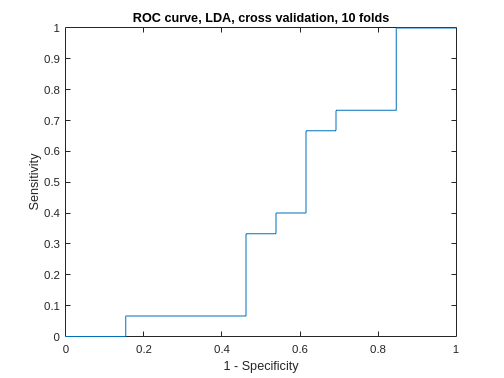

     Cross-valid-Test  Nrep  TP=  9 FN=  6; FP=  8 TN=  5; Se:  60.00 Sp:  38.46 CA:  50.00 AUC:  44.32
     Cross-valid-Learn Nrep  TP=  9 FN=  6; FP=  8 TN=  5; Se:  60.00 Sp:  38.46 CA:  50.00 AUC:  62.76
   Leave one o-Test   TP=  9 FN=  6; FP=  8 TN=  5; Se:  60.00 Sp:  38.46 CA:  50.00 AUC:  38.46
   Leave one o-Learn  TP=  9 FN=  6; FP=  8 TN=  5; Se:  60.00 Sp:  38.46 CA:  50.00 AUC:  62.80
QDA
   All records-Test   TP= 12 FN=  3; FP=  8 TN=  5; Se:  80.00 Sp:  38.46 CA:  60.71 AUC:  62.56
   All records-Learn  TP= 12 FN=  3; FP=  8 TN=  5; Se:  80.00 Sp:  38.46 CA:  60.71 AUC:  62.56
   20% holdout-Test  Single  TP=  1 FN=  2; FP=  2 TN=  0; Se:  33.33 Sp:   0.00 CA:  20.00 AUC:  16.67
   20% holdout-Learn Single  TP=  1 FN=  2; FP=  2 TN=  0; Se:  33.33 Sp:   0.00 CA:  20.00 AUC:  71.97
     20% holdout-Test  Nrep  TP=  2 FN=  1; FP=  1 TN=  1; Se:  66.67 Sp:  50.00 CA:  60.00 AUC:  50.56
     20% holdout-Learn Nrep  TP=  2 FN=  1; FP=  1 TN=  1; Se:  66.67 Sp:  50.00 CA:  60

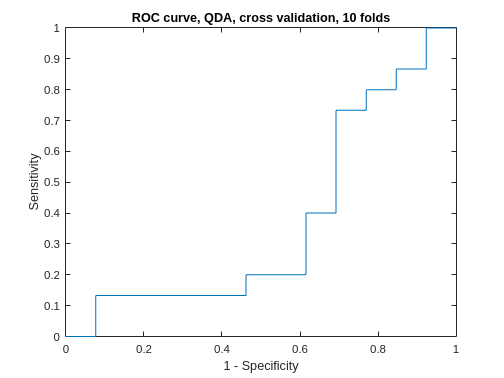

     Cross-valid-Test  Nrep  TP= 10 FN=  5; FP=  8 TN=  5; Se:  66.67 Sp:  38.46 CA:  53.57 AUC:  41.95
     Cross-valid-Learn Nrep  TP= 10 FN=  5; FP=  8 TN=  5; Se:  66.67 Sp:  38.46 CA:  53.57 AUC:  65.83
   Leave one o-Test   TP=  9 FN=  6; FP=  8 TN=  5; Se:  60.00 Sp:  38.46 CA:  50.00 AUC:  34.87
   Leave one o-Learn  TP=  9 FN=  6; FP=  8 TN=  5; Se:  60.00 Sp:  38.46 CA:  50.00 AUC:  64.79


doClassification('featureVectors.txt', 'referenceClass.txt', {1, 1}, 10, 30, 0)